## **Računalno upravljanje sustavima**

## **2. Laboratorijska vježba**

## **Laplaceova tranformacija i pokazatelji kvalitete odziva**

### **1. Uvod**

Laplaceova transformacija (L-transformacija) najvažnije je pomoćno sredstvo za rješavanje linearnih diferencijalnih jednadžbi s konstantnim koeficijentima. Laplaceova transformacija koristi se za analizu električkih krugova, oscilatora, optičkih naprava ili mehaničkih sustava. U ovim razmatranjima Laplaceova transformacija se tumači kao transformacija iz područja vremena, gdje su ulazne i izlazne veličine funkcije vremena *t*, u područje kompleksne kružne frekvencije *s*. Laplaceova transformacija na taj način često znatno pojednostavljuje analizu i sintezu sustava.

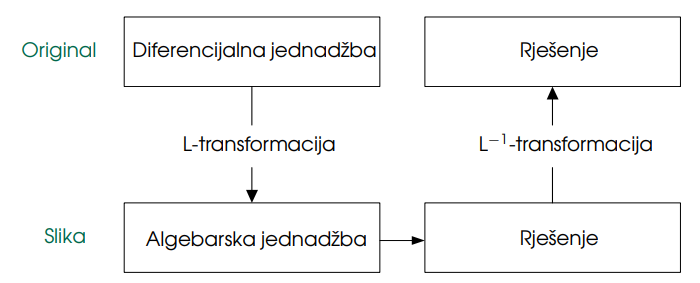

*Slika 1. *Rješavanje diferencijalne jednadžbe korištenjem L-transformacije

Laplaceova transformacija je linearna integralna transformacija definirana kao: 

                                           $F\left(s\right)=\int_{0^- }^{\infty } f\left(t\right)e^{-\textrm{st}} \;\textrm{dt}$,                                         (1)

gdje je$f\left(t\right)\;$orginalna funkcija, $F\left(s\right)$ slika funkcije, a $s=\sigma +j\omega$ kompleksna varijabla.

Definicija Laplaceove transformacije temelji se na pretpostavkama: 

- $f\left(t\right)=0$ za $t<0$ (za kauzalne sustave)

- kompleksna varijabla $s$ nalazi se u području konvergencije integrala.

Primjenimo sada Laplaceovu transformaciju na sustav akcelerometra iz prve laboratorijske vježbe opisan diferencijalnom jednadžbom

                                     $m\ddot{x} \left(t\right)+b\dot{x} \left(t\right)+\textrm{kx}\left(t\right)=F\left(t\right)$,                                     (2)

gdje je $m$ masa, $b$ koeficijent prigušenja prigušnice, $k$ koeficijent elastičnosti opruge, $F$ inercijalna sila u smjeru $x$, a $x$ pomak mase iz ravnotežnog stanja.

Koristeći svojstva L-transformacije spomenuta na predavanju i uz pretpostavku da su početni uvjeti jednaki nuli, diferencijalnu jednadžbu moguće je prebaciti u fekvencijsku domenu na sljedeći način:

 
$$\mathcal{L}\left\lbrace m\ddot{x} \left(t\right)+b\dot{x} \left(t\right)+\textrm{kx}\left(t\right)\right\rbrace =\mathcal{L}\left\lbrace F\left(t\right)\right\rbrace$$
   


$$\mathcal{L}\left\lbrace m\ddot{x} \left(t\right)\right\rbrace +\mathcal{L}\left\lbrace b\dot{x} \left(t\right)\right\rbrace +\mathcal{L}\left\lbrace \textrm{kx}\left(t\right)\right\rbrace =\mathcal{L}\left\lbrace F\left(t\right)\right\rbrace$$
    


$${\textrm{ms}}^2 X\left(s\right)+\textrm{bsX}\left(s\right)+\textrm{kX}\left(s\right)=F\left(s\right)$$
    

 
$$\left.{X\left(s\right)\;\left(\textrm{ms}\right.}^2 +\textrm{bs}+k\right)=F\left(s\right)$$
       

                                      $X\left(s\right)=\;\frac{F\left(s\right)}{{\textrm{ms}}^2 +bs+k}$.                                               (3)

Prijenosnu funkciju sustava definirana je kao omjer izlaznog i ulaznog signala u Laplaceovoj domeni: 

                                    $G\left(s\right)=\frac{X\left(s\right)}{F\left(s\right)}=\frac{1}{{\textrm{ms}}^2 +bs+k}$.                                     (4)

U analizi i sintezi sustava upravljanja Laplaceova transformacija nam, između ostalog, služi za određivanje pokazatelja kvalitete prijelazne funkcije u vremenskom području. Na primjer, određivanjem korjena nazivnika prijenosne funkcije (polova sustava) možemo odrediti je li sustav stabilan ili ne te podesiti parametre regulatora kako bi sustav bio stabilan i imao željenu brzinu odziva.

Cilj ove vježbe je naučiti kako položaj polova i nula prijenosne funkcije sustava utječe na dinamičko vladanje sustava te kako parametrirati sustav tako da se postignu određeni zahtjevi na vladanje sustava (nadvišenje te brzina odziva).

### 2.  Prijenosna funkcija

Zadan je sustav opisan sljedećom diferencijalnom jednadžbom:

                              $a_2 \ddot{x} \left(t\right)+a_1 \dot{x} \left(t\right)+a_0 x\left(t\right)=b_1 \dot{u} \left(t\right)+b_0 u\left(t\right)$                         (5)

Odredite prijenosnu funkciju sustava (nadopunite jednadžbu):

                                                    $G\left(s\right)=\frac{X\left(s\right)}{U\left(s\right)}=$$\frac{sb_1 + b_0}{s^2a_2 + sa_1 + a_0}$                                             (6)

a0 = 1.37;
a1 = 3.17;
a2 =     1; % budući je prijenosna funkcija razlomak kojeg možemo pokratiti, možemo fiksirati jedan parametar na 1

b0 = 5;
b1 = -1.32;

Pokrenite Simulink i modelirajte zadani sustav (predlažemo korištenje bloka "`Transfer Fcn`" u koji se mogu upisati koeficijenti $a_0$, $a_1$, $a_2$ i $b_0$, $b_1$ definirani u Matlab workspace-u). Na ulaz sustava dovedite signal $u\left(t\right)=3S\left(t-2\right)$ (blok "`Step`" u Simulinku), a izlaz sustava prikažite grafički pomoću bloka "`Scope`".

Simulirajte kreirani model sustava za različite vrijednosti koeficijenata, pri čemu podesite vrijeme simulacije tako da je vidljiva cijela prijelazna pojava. Promjena vrijednosti koeficijenata ostvaruje se pomicanjem klizača.

### 3.  Polovi i nule sustava

Za analizu sustava i njihovo upravljanje prikladno je prijenosnu funkciju $G\left(s\right)$prikazati u faktoriziranom obliku, odnosno pomoću nula i polova sustava. Iz prijelazne funkcije sustava (6) vidi se da je brojnik prvog reda, a nazivnik drugog reda. Iz toga proizlazi da sustav ima jednu konačnu nulu i dva pola, te je prijenosnu funkciju moguće prikazati u obliku

                                            $G\left(s\right)=K\frac{\left(s-n_1 \right)}{\left(s-p_1 \right)\left(s-p_2 \right)}$,                                   (7)

gdje je $K$ pojačanje sustava, $n_1$ nula sustava, a $p_1$ i $p_2$ polovi.

Izrazite nulu, polove i pojačanje sustava preko koeficijenata $a_0$, $a_1$, $a_2$, $b_0$ i $b_1$.

a0 = 1.5;
a1 = 1.5;
a2 =     1;     %

b0 = 5;
b1 = 1.16;

s = tf('s');  % kompleksna varijabla s

% U sljedećem retku unesite prijenosnu funkciju pomoću varijable s i
% definiranih koeficijenata.
G = (s*b1+b0)/(s^(2)*a2+s*a1+a0);

% Izračunajmo nulu i polove pomoću funkcije pzmap
[polovi, nule] = pzmap(G)

polovi =   -0.7500 + 0.9682i
  -0.7500 - 0.9682i


nule = -4.3103

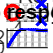


% Simulacija sustava na step pobudu
[y, t] = step(G);

figure(1);
clf;

% grafički prikaz nula i polova
subplot(2,1,1);
hold on;
grid on;
grid minor;
% nule prikazujemo pomoću crvenih kružića:
plot(real(nule), imag(nule), 'r', 'Marker', 'o', 'LineStyle', 'none', 'LineWidth', 1.5);
% polove prikazujemo pomoću plavih križića:
plot(real(polovi), imag(polovi), 'b', 'Marker', 'x', 'LineStyle', 'none', 'LineWidth', 1.5);
% postavljanje osi x i y
set(gca,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('Re');
ylabel('Im');
title('Pole-zero Map');

% grafički prikaz odziva
subplot(2,1,2);
hold on;
grid on;
grid minor;
plot(t, y, 'b', 'LineWidth', 1.5);
plot([t(1), t(end)],[y(end), y(end)], 'k--');
xlim([0,t(end)]);
ylim([min(y)-0.1, max(y)+0.1]);
xlabel('$t$ [s]', 'Interpreter', "latex");
ylabel('$y$', 'Interpreter', 'latex');
title('Step response');

 Kakvo je ponašanje sustava kada: 

- polovi imaju samo realnu komponentu, - sustav bez oscilacija postiže konačnu vrijednost (realna komponenta je negativna)

- polovi imaju samo imaginarni dio, - sustav beskonačno dugo oscilira oko neke konačne vrijednosti.

- su polovi konjugirano-kompleksni parovi, - sustav prigušeno oscilira dok ne postigne konačnu vrijednost.

- je barem jedan pol u desnoj poluravnini, - sustav je nestabilan, sa $t=\infty \to G\left(t\right)=\infty$.

- je nula u desnoj poluravnini. - sustav je nestabilan, sa $t=\infty \to G\left(t\right)=\infty$.

### 4. Pokazatelji kvalitete odziva

Svaki sustav drugog reda bez konačnih nula moguće je prikazati u obliku

                                     $G\left(s\right)=\frac{K\;\omega_n^2 }{s^2 +2\zeta \omega_n \;s+\omega_n^2 }$,                                           (8)

gdje je $K$ pojačanje, $\zeta$ faktor prigušenja te $\omega_n$ prirodna frekvencija. Ako vrijedi $0<\zeta <1$sustav je stabilan i ima oscilatorno vladajne. Za sustav iz prve laboratorijske vježbe zadan diferecijalnom jednadžbom $m\ddot{x} \left(t\right)+b\dot{x} \left(t\right)+\textrm{kx}\left(t\right)=F\left(t\right)$izrazite pojačanje, faktor prigušenja te prirodnu frekvenciju preko parametara $m$, $b$ i $k$.

Podesite parametre $m$, $b$ i $k$ tako da sustav bude jediničnog pojačanja te da vrijeme maksimuma i nadvišenje budu $t_m =2\;\mathrm{s}$ te $\sigma_m =5%$.

t_m = 2;
sigma_m = 5;

% Upišite izračunate vrijednosti
m = 0.2125;
b = 0.6365;
k = 1;

G = tf(1, [m b k]); % prijenosna funkcija gdje je brojnik 1, a nazivnik polinom s koeficijentima m, b i k

figure(2);
clf;

stepinfo(G) % pokazatelji kvalitete

ans = struct with fields:
         RiseTime: 0.9671
    TransientTime: 2.7635
     SettlingTime: 2.7635
      SettlingMin: 0.9001
      SettlingMax: 1.0499
        Overshoot: 4.9885
       Undershoot: 0
             Peak: 1.0499
         PeakTime: 1.9987


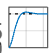

step(G) % odziv na step
grid on;

%#ok<*NASGU> Ovo spriječava Matlabova upozorenja da se varijabla ne koristi